%r0748760 8 7 7 6 4
Tnew = (8*T1 + 7 *T2 + 7*T3 + 6*T4 + 4*T5)/(8+7+7+6+4);

X1training = X1(1:1000);
X1validation = X1(1001:2000);
X1test = X1(2001:3000);

X2training = X2(1:1000);
X2validation = X2(1001:2000);
X2test = X2(2001:3000);

T3training = Tnew(1:1000);
T3validation = Tnew(1001:2000);
T3test = Tnew(2001:3000);

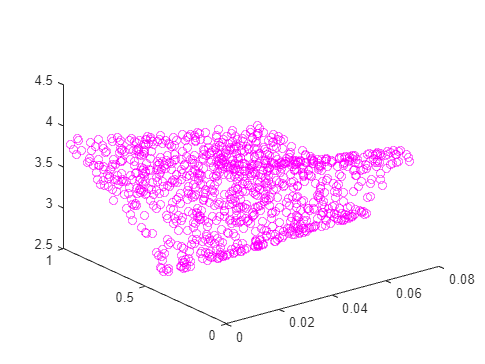

%Scatteredinterpolant creation and figure
%linspace creates a vector of values, take three arguments: 'start', 'stop' and 'n'. Start and stop are selfexplanatory, n is the number of evenly spaced values that are generated between start and stop.
X = linspace(min(X1training),max(X1training),25); 
Y = linspace(min(X2training),max(X2training),25); 
%meshgrid creates a gird of coordinates for given range x and y.
[xq, yq] = meshgrid(X,Y); 
%scatteredInterpolant takes a set of scattered data points and constructs a surface that passes throught these points. This surface can then be used to interpolate values at new points within the range of original data
F1 = scatteredInterpolant(X1training,X2training,T3training);

zq = griddata(X1training,X2training,T3training,xq,yq); 
plot3(X1training,X2training,T3training,'mo')
hold on

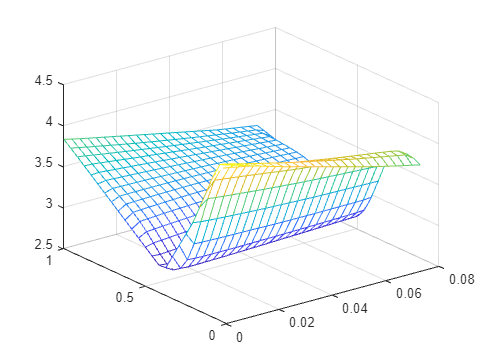

figure
vq1 = F1(xq,yq);
mesh(xq,yq,vq1)
hold off

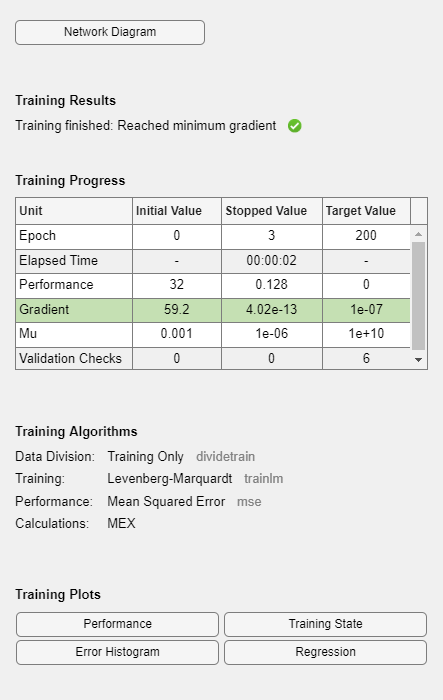

%Neural network creation net1
x1 = X1training;
x2 = X2training;
t1 = T3training;
Xcomb = horzcat(X1training, X2training);

net1 = feedforwardnet(10,'trainlm');
net2 = feedforwardnet(10,'trainlm');

net1=configure(net1,Xcomb',t1');
net2=configure(net2,Xcomb',t1');


net1=init(net1);% Initialize the weights (randomly)
net2.iw{1,1}=net1.iw{1,1};% Set the same weights and biases for the networks 
net2.lw{2,1}=net1.lw{2,1};
net2.b{1}=net1.b{1};
net2.b{2}=net1.b{2};


%net1.layers{1}.transferFcn = 'purelin';
%net1.layers{2}.transferFcn = 'purelin';
net1.divideFcn = 'dividetrain';% Use training set only (no validation and test split)
net1.trainParam.epochs=200;
net1 = train(net1, Xcomb',t1');

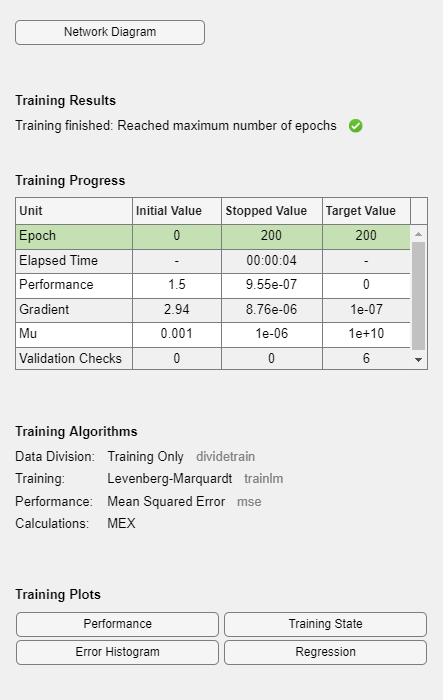


net2.trainParam.epochs=200;
net2.divideFcn = 'dividetrain';
net2 = train(net2, Xcomb',T3training');

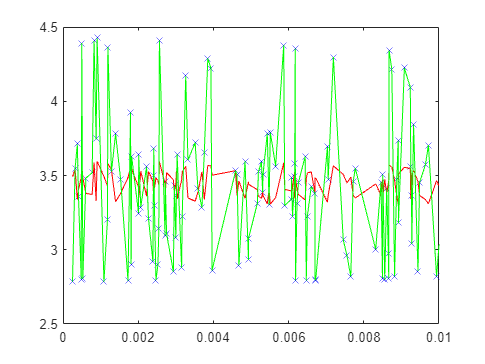


%Comparison script


a1=sim(net1,Xcomb');
a2=sim(net2,Xcomb');

figure

plot(x1,t1,'bx',x1,a1,'r',x1,a2,'g');
xlim([0 0.01])
ylim([2.5 4.5])

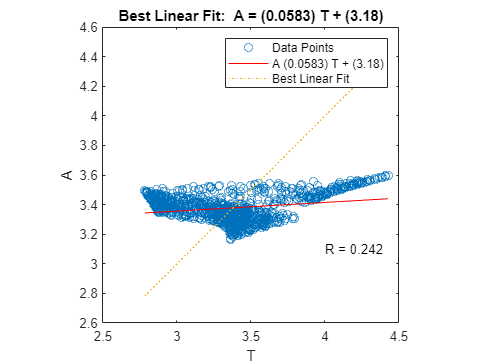

postregm(a1,t1'); % perform a linear regression analysis and plot the result

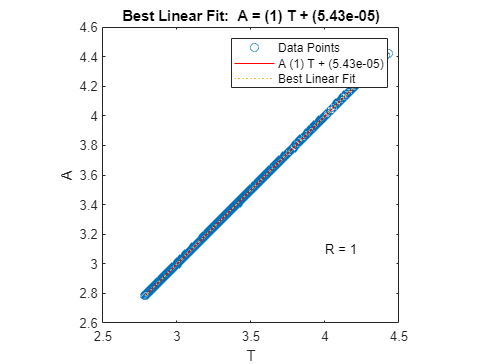

postregm(a2,t1');


XvalComb = horzcat(X1validation,X2validation)

XvalComb =     0.0730    0.5029
    0.0735    0.8534
    0.0736    0.2156
    0.0736    0.0230
    0.0737    0.7646
    0.0737    0.4253
    0.0737    0.3394
    0.0738    0.6013
    0.0739    0.9621
    0.0740    0.9698


outputs1 = net1(XvalComb');
performance1 = perform(net1,T3validation,outputs1)

performance1 = 0.0706

outputs2 = net2(XvalComb');
performance = perform(net2,T3validation,outputs2)

performance = 0.1219